## Nacht

#### Verwarming aan 's nachts (OUD)

Q_nacht_straling = pool_area*epsilon_mat*sigma*((temp_water+273)^4- (gebouw_temp+273)^4)

Q_nacht_straling = 1.0376e+03

Q_nacht_convection = alpha *pool_area  *  (temp_water-gebouw_temp)

Q_nacht_convection = 1.0718e+03

Q_nacht_latent = Q_latent * 0.02

Q_nacht_latent = 126.4170

Q_nacht_out = Q_nacht_straling+Q_nacht_convection + Q_nacht_latent

Q_nacht_out = 2.2359e+03

#### Verwarming uit 's nachts

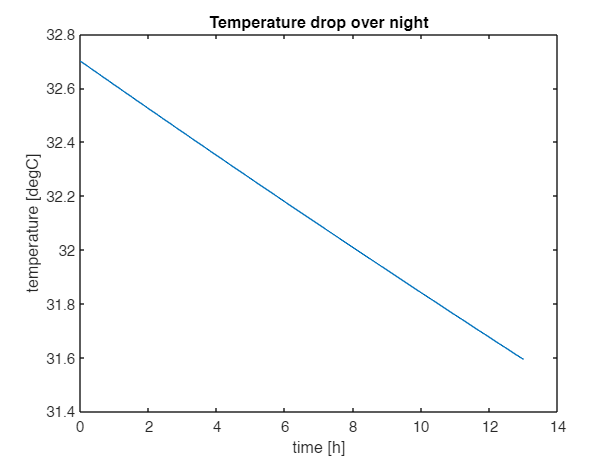

f_nacht = @(t_nacht,T_nacht) (-alpha * pool_area  *  ((T_nacht-273)-gebouw_temp_nacht) - pool_area*epsilon_mat*sigma*((T_nacht)^4- (gebouw_temp_nacht+273)^4))/(rho*volume*cpw); 
tspan_nacht = [0 (24-operationele_uren)*3600];
T0_nacht  = temp_water+273;
[t_nacht, T_nacht] = ode45(f_nacht,tspan_nacht,T0_nacht);
plot(t_nacht/3600, T_nacht-273)
xlabel('time [h]')
ylabel('temperature [degC]')
title('Temperature drop over night')

## Weekend

tspan_weekend = [0 3600 * weekend_uren];
T0_weekend = temp_water+273

T0_weekend = 305.7000

[t_weekend,T_weekend] = ode45(f_nacht, tspan_weekend, T0_weekend);

Q_vector = alpha * pool_area  *  ((T_weekend-273)-gebouw_temp_nacht) + pool_area*epsilon_mat*sigma*((T_weekend).^4- (gebouw_temp_nacht+273)^4);
verloren_energie_weekend = sum(Q_vector*10^(-3)*(t_weekend(2)-t_weekend(1))/3600) %[kWh]

verloren_energie_weekend = 211.7408

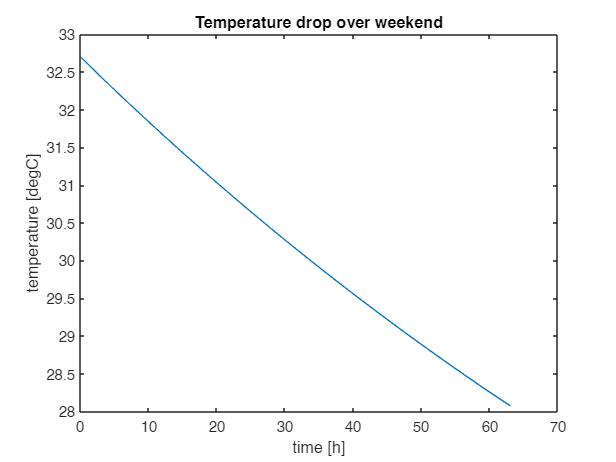

plot(t_weekend/3600, T_weekend-273)
xlabel('time [h]')
ylabel('temperature [degC]')
title('Temperature drop over weekend')

## Opstart

Q_opstart_in = 75*10^3;

temp_ruimte = 22

temp_ruimte = 22

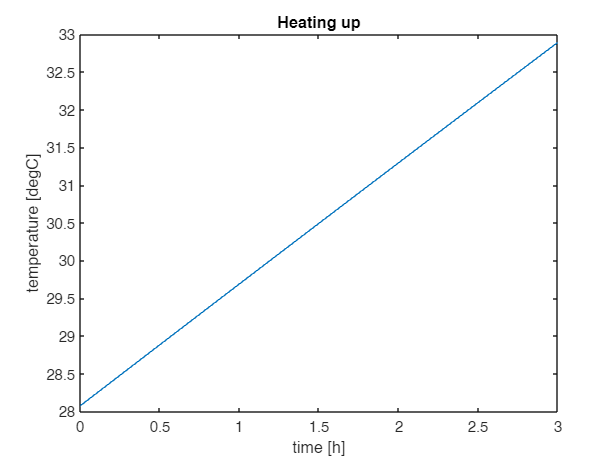

f_opstart = @(t_opstart,T_opstart) (Q_opstart_in - alpha * pool_area  *  ((T_opstart-273)-gebouw_temp_nacht) - pool_area*epsilon_mat*sigma*((T_opstart)^4- (gebouw_temp_nacht+273)^4))/(rho*volume*cpw); 
tspan_opstart = [0 3600 * 3];
T0_opstart = T_weekend(end);
[t_opstart,T_opstart] = ode45(f_opstart, tspan_opstart, T0_opstart);

% idx = interp1(T_opstart, 1:length(T_opstart), 34+273, 'nearest')
% t_opstart(idx)/3600

% kost_opstart = Q_opstart_in  *10^(-3) * t_opstart(idx)/3600 *0.13
% totaal_kost_opstart = kost_opstart + weekend_uren*Q_in_weekend*10^(-3)*0.13
% kost_opstart_alternatief = Q_nacht_out * 10^(-3) * weekend_uren * 0.13
plot(t_opstart/3600, T_opstart-273)
xlabel('time [h]')
ylabel('temperature [degC]')
title('Heating up')